Lab1

uppgift 1)

clear
clf


n = 0.8/0.02;

u = [0 ones(1, n-1)] % index 1 är noll då matlab suger

u =      0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1



y(1) = 0

y = 0

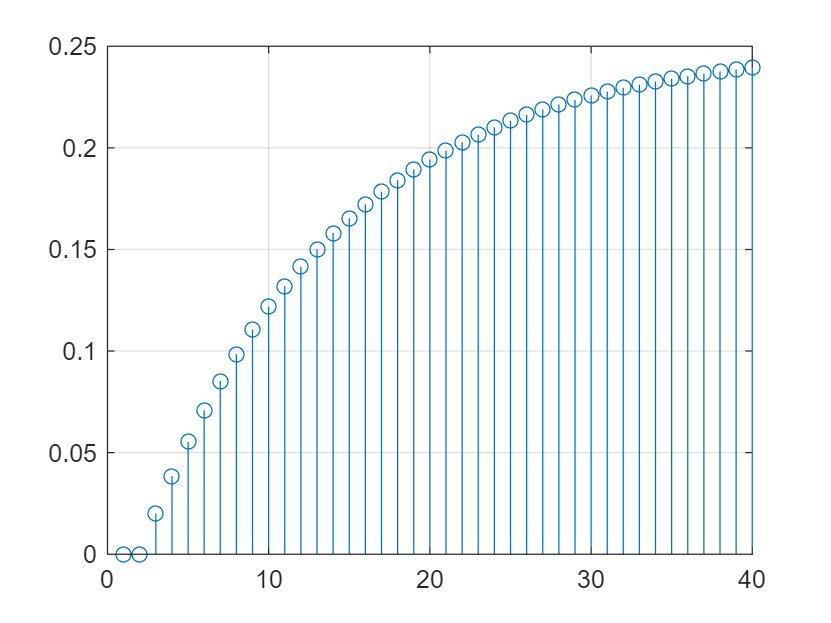


for m = 2:40
    y(m)=0.92*y(m-1)+0.02*u(m-1);
end


figure(1); stem(y); grid; xlim([0 40]);

% konvergerar mot 0.25 vilket är rimligt då
% 0.02/0.08 = 0.25

uppgift 3)

clear
clf

t = 0:0.02:0.8;

y = 1/4 - exp(-4*t)/4

y =          0    0.0192    0.0370    0.0533    0.0685    0.0824    0.0953    0.1072    0.1182    0.1283    0.1377    0.1463    0.1543    0.1616    0.1684    0.1747    0.1805    0.1858    0.1908    0.1953    0.1995    0.2034    0.2070    0.2103    0.2133    0.2162    0.2188    0.2212    0.2234    0.2254    0.2273    0.2291    0.2307    0.2322    0.2335    0.2348    0.2360    0.2370    0.2380    0.2390    0.2398


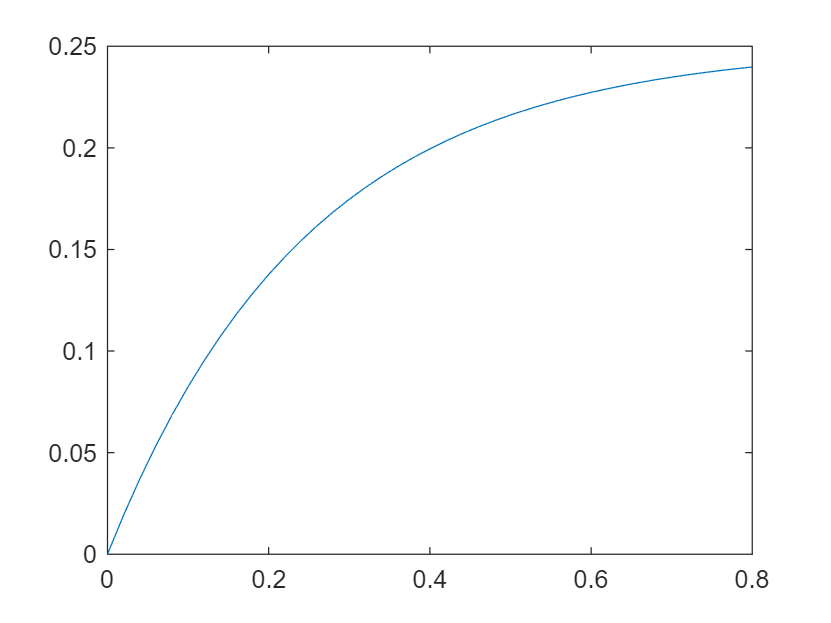


plot(t,y)

uppgift 4)

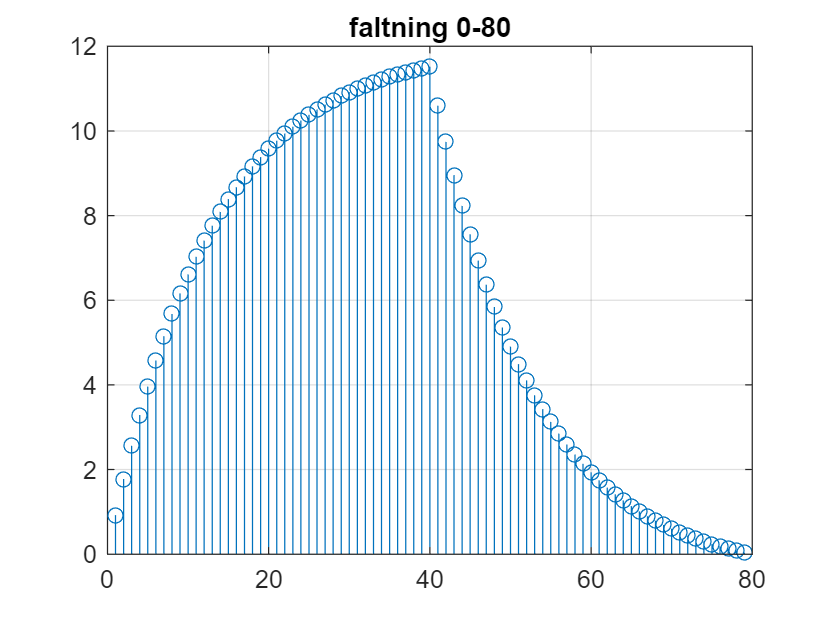

clear
clf

x = [ones(1,40)];

T = 0.02;
n = 1:40;
h = exp(-4*n*T); % t = n * T impulssvar

y = conv(x,h);



stem(y);
grid on;
title('faltning 0-80')

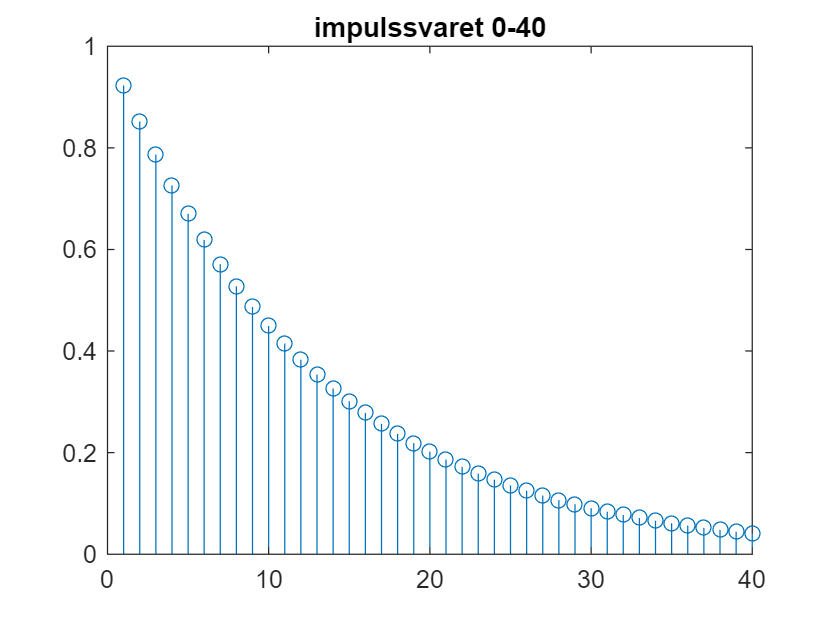


stem(h);
title('impulssvaret 0-40')

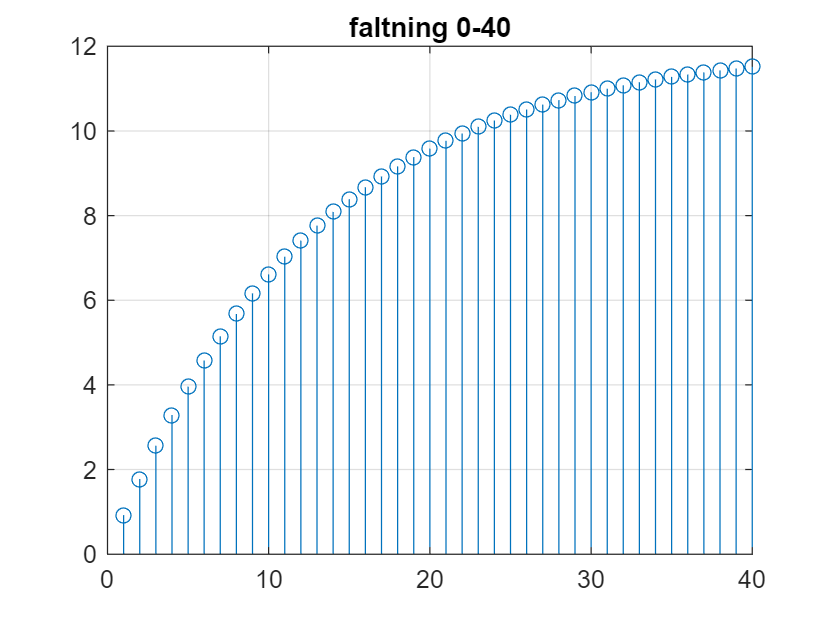


y=y(n);
figure(4); stem(y); grid;
title('faltning 0-40')

uppgift 5)

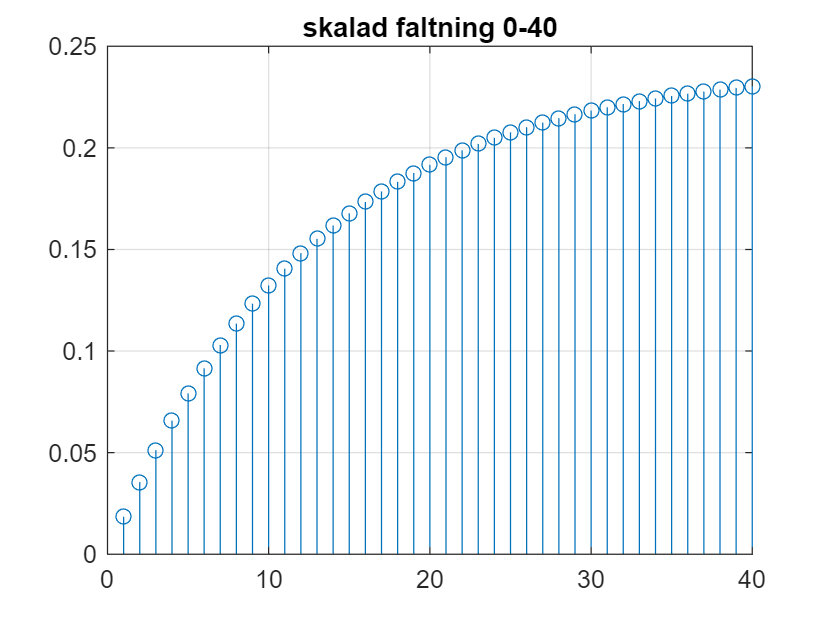

z = y * T;

figure(5); stem(z); grid;
title('skalad faltning 0-40')

uppgift 6)

clear
clf

[y, fs]=audioread("nocturne.wav");
delay = round(0.3*fs)

delay = 3308

h = [1 zeros(1,delay) 1 zeros(1,delay)]

h =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


mixtape = conv(y, h);
soundsc(mixtape,fs) %reverb ))))

2.1 **Ljudsignaler**

uppgift 7)

clear
clf

load piano1.mat
%soundsc(y1, 1/2*fs)
plot(y1)

uppgift 8)

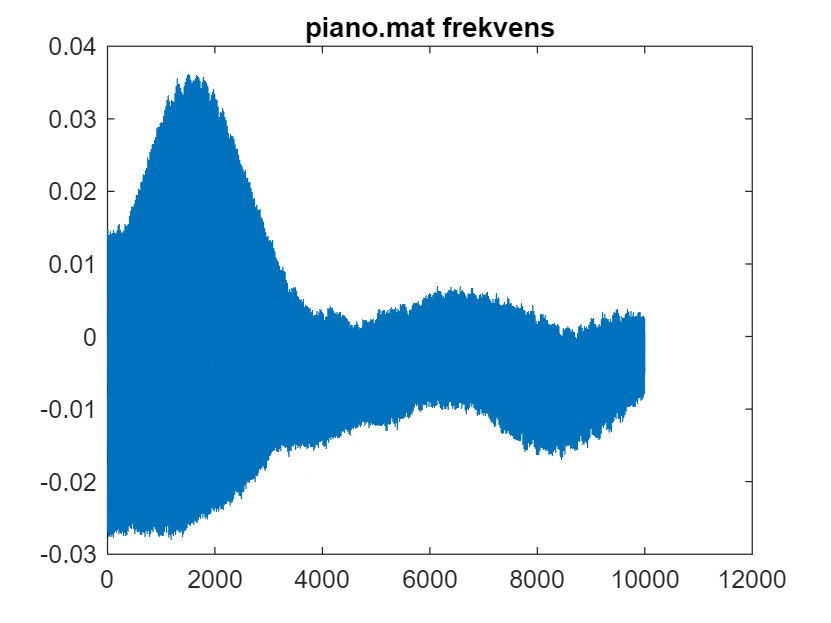


title('piano.mat frekvens')

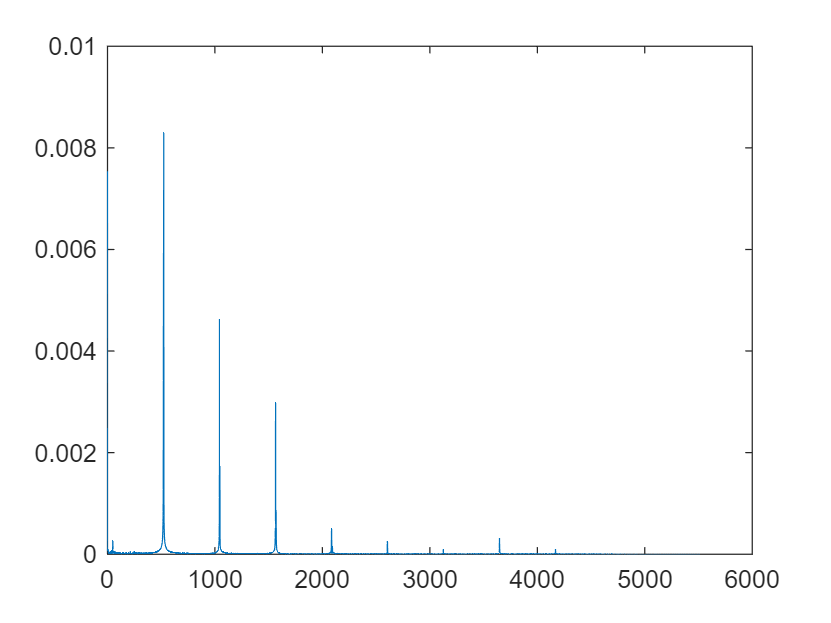


Y = fft(y1);
n = length(Y);
f = 0:(fs/n):fs/2;
X_magnitude = abs(Y)/(n/2);
plot(f, X_magnitude(1:length(f)))

[maxfisk,maxval]=(max(Y))

maxfisk = -3.5184 + 41.3459i

maxval = 476

abs(maxfisk)

ans = 41.4954


deltaf = fs/n

deltaf = 1.1024

maxfreq = maxval * deltaf

maxfreq = 524.7375

maxfreq + deltaf

ans = 525.8399

maxfreq - deltaf

ans = 523.6351